# Fuel Economy Analysis

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

autoData = readtable("./data/autoData.csv");
hp = autoData.hp;
mpg = autoData.mpg;
wt = autoData.wt;
whos

  Name           Size            Bytes  Class     Attributes

  autoData      50x3              2605  table               
  hp            50x1               400  double              
  mpg           50x1               400  double              
  wt            50x1               400  double              



## Task 1

nanIdx = ismissing(mpg)

nanIdx = 50×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


mpg = mpg(~nanIdx);
hp = hp(~nanIdx);
wt = wt(~nanIdx);

## Task 2

Fuel economy in the U.S. is typically given in miles/gallon. In many countries, however, the standard units are liters/100km.

Given `mpg`, you can calculate economy in L/100km by dividing `235.214583` by `mpg`.

econ = 235.214583 ./ mpg

econ =     6.5886
    9.0467
    6.5337
    6.1899
    7.3505
    6.3230
    7.2822
    8.7117
    5.0475
    8.4005


numdata = [wt hp econ]

numdata = 1.0e+03 *

    1.9150    0.0800    0.0066
    1.9630    0.0670    0.0090
    1.9800    0.0740    0.0065
    1.9950    0.0670    0.0062
    2.0030    0.0610    0.0074
    2.0190    0.0650    0.0063
    2.0650    0.0670    0.0073
    2.1000    0.0880    0.0087
    2.1100    0.0650    0.0050
    2.1250    0.0750    0.0084


## Task 3

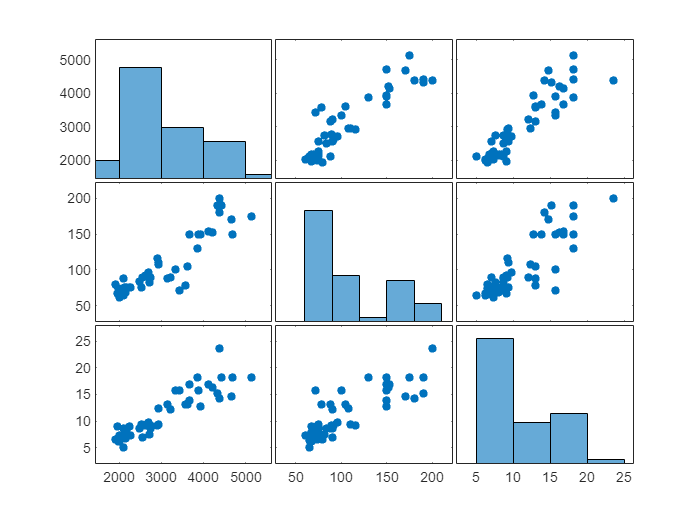

plotmatrix(numdata)

cc = corrcoef(numdata)

cc =     1.0000    0.9060    0.9070
    0.9060    1.0000    0.8347
    0.9070    0.8347    1.0000


## Task 4

p = polyfit(wt, econ, 1)

p =     0.0042   -1.4443


econFit = polyval(p, wt)

econFit =     6.6251
    6.8273
    6.8990
    6.9622
    6.9959
    7.0633
    7.2571
    7.4046
    7.4467
    7.5100


## Task 5

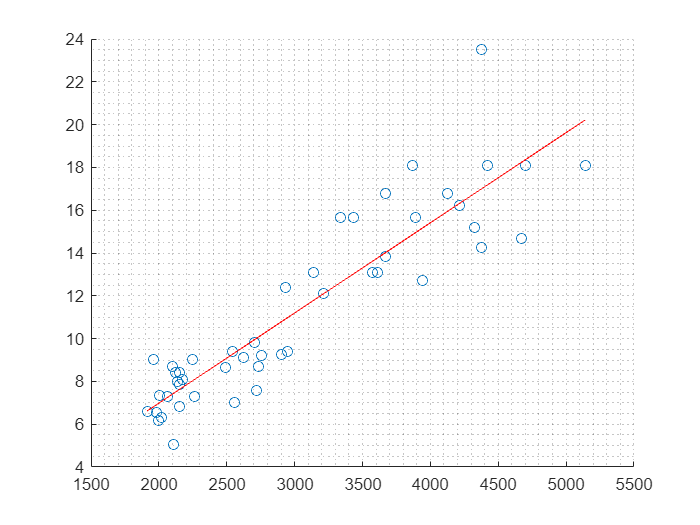

scatter(wt, econ)
hold on
plot(wt, econFit, "r")
grid minor
hold off